# Design controllers

clear all
close all
clc

load modello_j1.mat
load modello_j2.mat

max_acc=10; % rad/s^2
vel_max=10; % rad/s
st=1e-3;

s=tf('s');
p1=[modello_continuo_tf_j1/s;
    modello_continuo_tf_j1];
[gpeak,fpeak] = getPeakGain(p1(2),[],[100 1000])

gpeak = 0.0038

fpeak = 222.7573

notch1=notch(fpeak) %calcolo notch dinamico all'interno della taratura/funzione di costo

notch1 =
 
  s^2 + 40.1 s + 4.962e04
  -----------------------
  s^2 + 401 s + 4.962e04
 
Continuous-time transfer function.



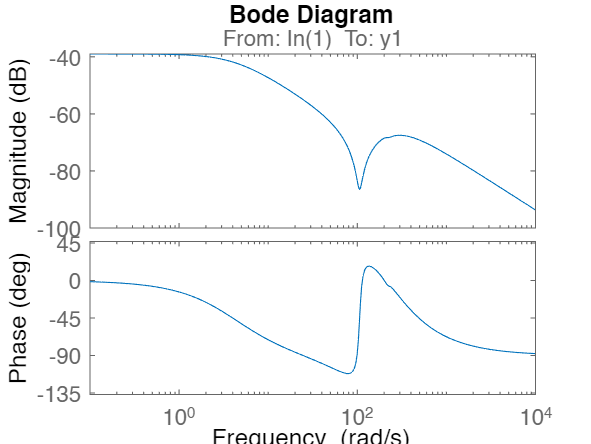

bode(p1(2)*notch1)


p2=[modello_continuo_tf_j2/s;
    modello_continuo_tf_j2];
[gpeak,fpeak] = getPeakGain(p2(2),[],[100 1000])

gpeak = 0.0078

fpeak = 302.1986

notch2=notch(fpeak)

notch2 =
 
  s^2 + 54.4 s + 9.132e04
  -----------------------
  s^2 + 544 s + 9.132e04
 
Continuous-time transfer function.



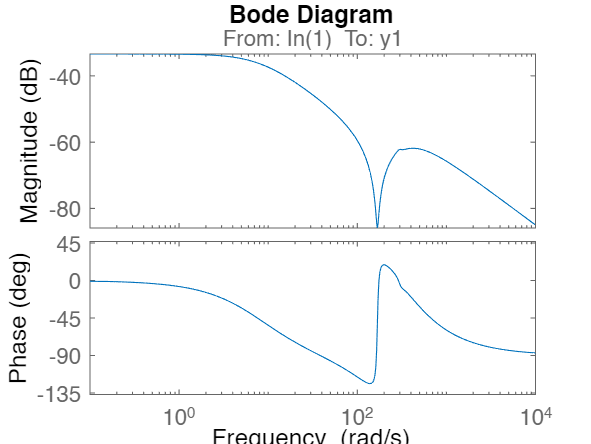

bode(p2(2)*notch2)


wc_des = 80;


Design reference

Dopo di che posso andare a definire il segnale eccitante, che partirà da una frequenza maggiore (almeno un decade).

w0=2; %rad/s
w1=max_acc; %rad/s
t=(0:st:5*(2*pi)/w0)';
control_action = vel_max*chirp(t,w0/2/pi,t(end),w1/2/pi, "logarithmic");
integrated_action = cumtrapz(t,control_action)

integrated_action =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


Sommo i due segnali

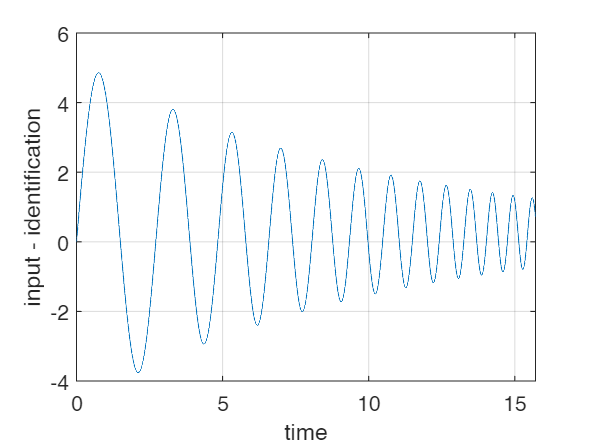

figure
plot(t,integrated_action)
xlabel('time')
ylabel('input - identification')
grid on

Initial tune 

j1

kp1_in=800;
p1=modello_continuo_tf_j1;
[gpeak,fpeak] = getPeakGain(p1*kp1_in,[],[100 1000])

gpeak = 3.0773

fpeak = 222.7573

if(gpeak > 1/10)
    filt=notch(fpeak,1/10/gpeak);
else
    filt=1;
end
Fin=feedback(p1*filt*kp1_in,1)/s

Fin =
 
  From input to output "y1":
                                              
    165.5 s^4 + 4295 s^3 + 1.01e07 s^2        
                                              
                       + 1.304e08 s + 9.232e10
                                              
  ----------------------------------------------
                                                
  s^6 + 612.3 s^5 + 1.216e05 s^4 + 3.235e07 s^3 
                                                
                  + 2.66e09 s^2 + 1.026e11 s    
                                                
 
Continuous-time transfer function.



[z, p, k]=zpkdata(Fin)

z = 1×1 cell array
    {4×1 double}


p = 1×1 cell array
    {6×1 double}


k = 165.4850

kp1=47.037;
Ti1=0.1932;
x1_0=[kp1 Ti1 kp1_in]

x1_0 =    47.0370    0.1932  800.0000


j2

kp2_in=360.7382;
p2=modello_continuo_tf_j2;
[gpeak,fpeak] = getPeakGain(p2*kp2_in,[],[100 1000])

gpeak = 2.8133

fpeak = 302.1986

if(gpeak > 1/10)
    filt2=notch(fpeak,1/10/gpeak);
else
    filt2=1;
end
Fin2=feedback(p2*filt2*kp2_in,1)/s

Fin2 =
 
  From input to output "y1":
                                             
   203 s^4 + 5916 s^3 + 2.431e07 s^2         
                                             
                      + 2.926e08 s + 5.234e11
                                             
  --------------------------------------------
                                              
  s^6 + 805 s^5 + 2.194e05 s^4 + 7.965e07 s^3 
                                              
                 + 8.974e09 s^2 + 5.912e11 s  
                                              
 
Continuous-time transfer function.



[z, p, k]=zpkdata(Fin2)

z = 1×1 cell array
    {4×1 double}


p = 1×1 cell array
    {6×1 double}


k = 203.0064

kp2=87.9358;
Ti2=0.89323;
x2_0=[kp2 Ti2 kp2_in]

x2_0 =    87.9358    0.8932  360.7382



cost1 = @(x) cascade_optimization_cost(x,modello_continuo_tf_j1,600,st,integrated_action,wc_des);
nonlcon1 = @(x) cascade_optimization_nonlcon(x,modello_continuo_tf_j1,60,2,logspace(1,3,1000))

nonlcon1 = function_handle with value:
    @(x)cascade_optimization_nonlcon(x,modello_continuo_tf_j1,60,2,logspace(1,3,1000))


cost2 = @(x) cascade_optimization_cost(x,modello_continuo_tf_j2,600,st,integrated_action,wc_des);
nonlcon2 = @(x) cascade_optimization_nonlcon(x,modello_continuo_tf_j2,60,2,logspace(1,3,1000))

nonlcon2 = function_handle with value:
    @(x)cascade_optimization_nonlcon(x,modello_continuo_tf_j2,60,2,logspace(1,3,1000))


% [cost, Y] = cost([1 1000 1000]);
% [Cin, Ceq] = nonlcon([1 1000 1000])
A=[1 0 -10]; b=0;

opt1=optimoptions("ga","MaxTime",3600*0.25,'InitialPopulation',x1_0);
x1=ga(cost1,3,A,b,[],[],[1 1e-6 1],[1e6 1e6 1e6],nonlcon1,opt1)
save Result x1
opt2=optimoptions("ga","MaxTime",3600*0.25,'InitialPopulation',x2_0);
x2=ga(cost2,3,A,b,[],[],[1 1e-6 1],[1e6 1e6 1e6],nonlcon2,opt2)
save Result x1 x2

tic
[J, Y, wc] = cost2(x2)
toc
nonlcon2(x2)

plot(t,integrated_action,t,Y)
legend("ref","out")


mul=100;
P=modello_continuo_tf_j1;
ss_vel=ss(P);
ss_vel_states=ss(ss_vel.A,ss_vel.B,eye(size(ss_vel.A)),zeros(size(ss_vel.A,1),size(ss_vel.B,2)));

ss_pos=ss(P/s);
ss_pos_states=ss(ss_pos.A,ss_pos.B,eye(size(ss_pos.A)),zeros(size(ss_pos.A,1),size(ss_pos.B,2)));
Y=zeros(1,length(integrated_action));
x0_vel=zeros(1,size(ss_vel.A,1));
x0_pos=zeros(1,size(ss_pos.A,1));
% sim matlab
Y_sim=lsim(ss_pos,integrated_action*mul,t,x0_pos)

% sim our method
tic
for i = 1 : length(integrated_action)
    vel=lsim(ss_vel,integrated_action(i)*ones(1,2)*mul,[0 st],x0_vel);
    x0_vel=lsim(ss_vel_states,integrated_action(i)*ones(1,2)*mul,[0 st],x0_vel);
    pos=lsim(ss_pos,integrated_action(i)*ones(1,2)*mul,[0 st],x0_pos);
    x0_pos=lsim(ss_pos_states,integrated_action(i)*ones(1,2)*mul,[0 st],x0_pos);
    y=[pos(end) vel(end)];
    x0_pos = x0_pos(end,:);
    x0_vel = x0_vel(end,:);
    Y(i)=y(1);
end
toc

plot(t,Y,t,Y_sim)
legend("our method","matlab")
error=Y_sim-Y';
plot(t,error)